# Projection on polytopes

clc
clf
clear all
close all
rng(0)

% run('DataPreparation.mlx');
% IS0 = load('ImitationLearning\TrainingData\Data\init_validation.mat').buffer_init.IS0;

# Data

% function [is, ixy, iB, iz, ie] = generate_data(is, A, pinvA, pinvN)
%     ixy = A * is;
%     iB  = pinvA * ixy;
%     iz  = is - iB;
%     iz = 2 * iz; % Force constraint violation
%     ie  = pinvN * iz;
%     is  = iB + iz;
% end

% idx = 1;
% [is, ixy, iB, iz, ie] = generate_data(IS0(:, idx), A, pinvA, pinvN)

ix_max = 4.2;
iy_max = 4;
is_max = 8.5;
ax = [1  1  1  0  0  0;
      0  0  0  1  1  1];
ay = [1  0  0  1  0  0;
      0  1  0  0  1  0;
      0  0  1  0  0  1];
A = [ax; -ay];
pinvA = pinv(A);
N = null(A, 'rational');
pinvN = pinv(N);
n = size(N, 2);
ix = ix_max * [1; -1];
iy = iy_max * [1; -0.5; -0.5];
ixy = [ix; -iy];
iB = pinvA * ixy;
ie = [0; 0];
iz = N * ie;
is = iB + iz;

original = struct();
original.is  = is;
original.ixy = ixy;
original.iB  = iB;
original.iz  = iz;
original.ie  = ie;

function benchmark(ie_proj, time, Niter, original, optimal_projection, name, A, N, Ac, bc)
    iz_proj = N * ie_proj;
    is_proj = original.iB + iz_proj;
    ixy_proj = A * is_proj;
    
    projection = struct();
    projection.ie = ie_proj;
    projection.iz = iz_proj;
    projection.is = is_proj;
    projection.ixy = ixy_proj;

    disp('============================================================')
    disp(strcat(['Comparation of projection method: ', name]))
    disp('  Original | Optimal | Actual')

    disp('is')
    disp([original.is, optimal_projection.is, projection.is]);
    % disp('ixy')
    % disp([original.ixy, optimal_projection.ixy, projection.ixy]);
    % disp('iB')
    % disp([original.iB, optimal_projection.iB, projection.iB]);
    % disp('iz')
    % disp([original.iz, optimal_projection.iz, projection.iz]);
    disp('ie')
    disp([original.ie, optimal_projection.ie, projection.ie]);
    
    disp(' ')
    fprintf('Time: %d\n', time)
    fprintf('Iterations: %d\n', Niter)
    fprintf('Original max constraint violation: %d\n', max(Ac * original.ie - bc))
    fprintf('Projection max constraint violation: %d\n', max(Ac * ie_proj - bc))
    disp('============================================================')
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Affine dimension     : 2
Bounded              : Yes
Number of facets     : 6
Number of vertices   : 6
Number of edges      : 6
Area                 : 135.1
Centroid             : [ 0 1.48e-16 ]
Chebyshev center     : [ -1.504 0.1038 ]
Inradius             : 4.596
Diameter             : 21.21



Visualize slice

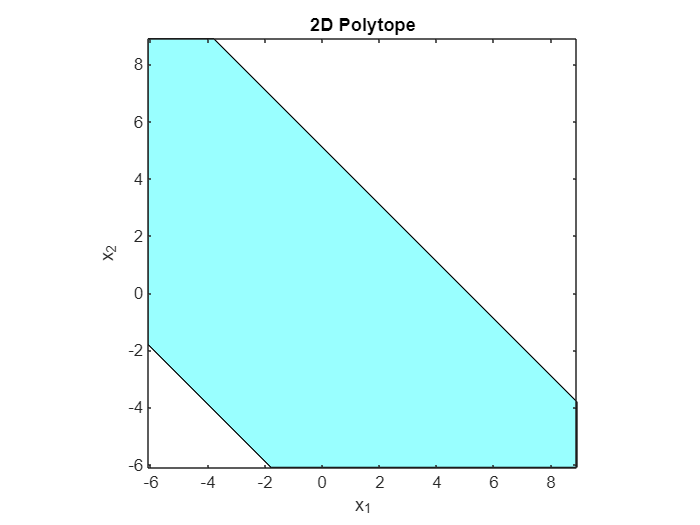

freeDim = 4;
visualizePolytope(Ac, bc, freeDim);

## Projector

Specifications

specsProjector = struct();

specsProjector.Ac      = Ac;
specsProjector.MaxIter = 100;
specsProjector.lambda  = 1;
specsProjector.Tol     = 1e-3;
specsProjector.Nx      = n;

## Quadratic programming solver

Create object

specsProjector.Method  = 'solver-qp';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

fprintf('Time: %d\n', time)

Time: 3.123000e-04


fprintf('Iterations: %d\n', Niter)

Iterations: 0


fprintf('Original max constraint violation: %d', max(Ac * original.ie - bc))

Original max constraint violation: -5.100000e+00

fprintf('Projection max constraint violation: %d', max(Ac * ie_proj - bc))

Projection max constraint violation: -5.100000e+00

## Scalar clipping

SUBOPTIMAL

Create object

specsProjector.Method  = 'scalar-clipping';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: scalar-clipping
  Original | Optimal | Actual
is
    3.4000    3.4000    3.4000
    0.4000    0.4000    0.4000
    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000
   -2.4000   -2.4000   -2.4000
   -2.4000   -2.4000   -2.4000
ie
     0     0     0
     0     0     0
 
Time: 1.039000e-04
Iterations: 0
Original max constraint violation: -5.100000e+00
Projection max constraint violation: -5.100000e+00


## Cimmino original

Mean of constraint violations

Create object

specsProjector.Method  = 'cimmino-original';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: cimmino-original
  Original | Optimal | Actual
is
    3.4000    3.4000    3.4000
    0.4000    0.4000    0.4000
    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000
   -2.4000   -2.4000   -2.4000
   -2.4000   -2.4000   -2.4000
ie
     0     0     0
     0     0     0
 
Time: 1.005000e-04
Iterations: 0
Original max constraint violation: -5.100000e+00
Projection max constraint violation: -5.100000e+00


## Cimmino greedy

SUBOPTIMAL

Max of constraint violations

Create object

specsProjector.Method  = 'cimmino-greedy';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: cimmino-greedy
  Original | Optimal | Actual
is
    3.4000    3.4000    3.4000
    0.4000    0.4000    0.4000
    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000
   -2.4000   -2.4000   -2.4000
   -2.4000   -2.4000   -2.4000
ie
     0     0     0
     0     0     0
 
Time: 1.046000e-04
Iterations: 0
Original max constraint violation: -5.100000e+00
Projection max constraint violation: -5.100000e+00


## Dykstra

Create object

specsProjector.Method  = 'dykstra';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: dykstra
  Original | Optimal | Actual
is
    3.4000    3.4000    3.4000
    0.4000    0.4000    0.4000
    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000
   -2.4000   -2.4000   -2.4000
   -2.4000   -2.4000   -2.4000
ie
     0     0     0
     0     0     0
 
Time: 3.840000e-04
Iterations: 0
Original max constraint violation: -5.100000e+00
Projection max constraint violation: -5.100000e+00


## Douglas Rachford

Create object

specsProjector.Method  = 'douglas-rachford';
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: douglas-rachford
  Original | Optimal | Actual
is
    3.4000    3.4000    3.4000
    0.4000    0.4000    0.4000
    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000
   -2.4000   -2.4000   -2.4000
   -2.4000   -2.4000   -2.4000
ie
     0     0     0
     0     0     0
 
Time: 6.000000e-06
Iterations: 0
Original max constraint violation: -5.100000e+00
Projection max constraint violation: -5.100000e+00


## Peaceman Rachford

Create object

specsProjector.Method = 'peaceman-rachford';
specsProjector.lambda = 0.5;
Projector = ClassProjector(specsProjector);

Project

[ie_proj, time, Niter] = Projector.project(ie, bc);

Compare

benchmark(ie_proj, time, Niter, original, optimal_projection, specsProjector.Method, A, N, Ac, bc)

Comparation of projection method: peaceman-rachford
  Original | Optimal | Actual
is
    3.4000    3.4000    3.4000
    0.4000    0.4000    0.4000
    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000
   -2.4000   -2.4000   -2.4000
   -2.4000   -2.4000   -2.4000
ie
     0     0     0
     0     0     0
 
Time: 6.100000e-06
Iterations: 0
Original max constraint violation: -5.100000e+00
Projection max constraint violation: -5.100000e+00


Projection layer

% layers = layerGraph(net);
% concatLayer = concatenationLayer(1, 2, 'Name', 'concat');
% projLayer = HardNetProjection('cimmino_max', M3C.A, M3C.N, M3C.C, is_max, Xmax, Ymax, 'projection');
% layers = addLayers(layers, concatLayer);
% layers = addLayers(layers, projLayer);
% layers = connectLayers(layers, net.Layers(end).Name, 'concat/in1');
% layers = connectLayers(layers, net.InputNames{1}, 'concat/in2');
% layers = connectLayers(layers, 'concat', 'projection');
% net = dlnetwork(layers);
% 
% plot(net)